# 2D Orbit Plotting Example

## Initialize Orbits

AU = 149597898; % [km]

a_kuat = 0.6 * AU; % [km]
e_kuat = 0;
% Create a true anomaly vector from 0 to 180 degrees with 100 elements
thetastar_kuat = linspace(0, deg2rad(180), 100);
w_kuat = deg2rad(40);

a_endor = 3.9 * AU; % [km]
e_endor = 0;
% Create a true anomaly vector from 0 to 270 degrees with 300 elements
thetastar_endor = linspace(0, deg2rad(270), 300);
w_endor = deg2rad(90);

% Example transfer
r_p_trans = 0.3 * AU;
r_a_trans = 4.2 * AU;
a_trans = (r_p_trans + r_a_trans) / 2;
e_trans = r_a_trans / a_trans - 1;
p_trans = a_trans * (1 - e_trans ^ 2);
% Rearrange orbit equation to get true anomaly when transfer orbit is at Kuat
thetastar_trans_0 = acos(1 / e_trans * (p_trans / a_kuat - 1));
% Rearrange orbit equation to get true anomaly when transfer orbit is at Endor
thetastar_trans_f = acos(1 / e_trans * (p_trans / a_endor - 1));
% Create true anomaly array for transfer orbit
thetastar_trans = linspace(thetastar_trans_0, thetastar_trans_f, 100);
w_trans = w_kuat - thetastar_trans_0;

## Plot

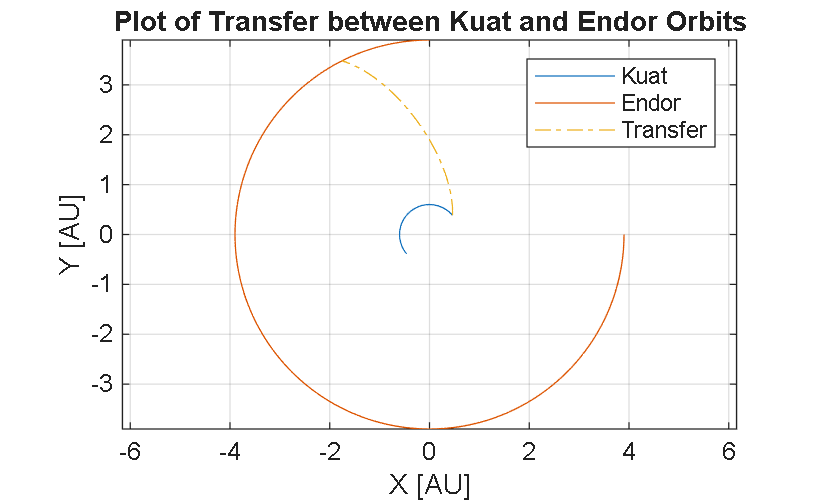

% Plot Kuat
orbitplot2D(a_kuat, e_kuat, thetastar_kuat, w_kuat, "Kuat", r_scale = AU); hold on
% Plot Endor
orbitplot2D(a_endor, e_endor, thetastar_endor, w_endor, "Endor", r_scale = AU, LineStyle = "-")
% Plot transfer
orbitplot2D(a_trans, e_trans, thetastar_trans, w_trans, "Transfer", r_scale = AU, LineStyle = "-.")
hold off
grid on
axis equal
title("Plot of Transfer between Kuat and Endor Orbits")
xlabel("X [AU]")
ylabel("Y [AU]")
legend()